## Clean Workspace

clear;
close;
clc;

## System Parameters

J1 = 1; % Moment of inertia of main body of the satellite
J2 = 1; % Moment of inertia of sensor module of the satellite

## System Model

E0 = diag([1 1 J1 J2]) % E matrix

E0 =      1     0     0     0
     0     1     0     0
     0     0     1     0
     0     0     0     1



Ap0 = [zeros(2) eye(2); zeros(2,4)] % A matrix of nominal system

Ap0 =      0     0     1     0
     0     0     0     1
     0     0     0     0
     0     0     0     0


Apk = [zeros(2,4); [-1 1; 1 -1] zeros(2)] % A matrix with affine dependence on parameter k

Apk =      0     0     0     0
     0     0     0     0
    -1     1     0     0
     1    -1     0     0


Apf = [zeros(2,4); zeros(2) [-1 1; 1 -1]] % A matrix with affine dependence on parameter f

Apf =      0     0     0     0
     0     0     0     0
     0     0    -1     1
     0     0     1    -1



Bp = [0; 0; 1; 0]

Bp =      0
     0
     1
     0



Dp = [0; 0; 1; 0]

Dp =      0
     0
     1
     0



Cp1 = [0 1 0 0]

Cp1 =      0     1     0     0



By1 = 0

By1 = 0


Dy = 0

Dy = 0


Cp2 = [1 0 0 0;
       0 1 0 0;
       0 0 0 0]

Cp2 =      1     0     0     0
     0     1     0     0
     0     0     0     0



By2 = [0; 0; 1]

By2 =      0
     0
     1



O = [0; 0; 0]

O =      0
     0
     0



pv = pvec('box',[0.09 0.4; 0.0038 0.04]) % Range of parameter variation

pv =     1.0000    0.0900    0.4000         0         0
    2.0000    0.0038    0.0400         0         0



% Parameter-dependent (uncertain) plant with affine dependence on k and f
Pol = psys(pv,[ltisys(Ap0, [Dp Bp], [Cp1; Cp2], [Dy By1; O By2], E0), ...
               ltisys(Apk, 0*[Dp Bp], 0*[Cp1; Cp2], 0*[Dy By1; O By2], 0), ...
               ltisys(Apf, 0*[Dp Bp], 0*[Cp1; Cp2], 0*[Dy By1; O By2], 0)])

Pol =      -Inf + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   1.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   4.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 - 1.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   4.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 - 1.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   4.0000 + 0.0000i   1.0000 + 0.0000i   0.0900 + 0.0000i   0.4000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i
   2.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   1.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 - 1.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 - 1.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.


psinfo(Pol); % Print open-loop system information

Affine parameter-dependent model with 2 parameters (3 systems) 
    Each system has 4 state(s), 2 input(s), and 4 output(s)



## Optimal Quadratic H∞ Performance

**Note:** Use the following inputs for `lmireg which correspond to intersection of the left half-plane with x < –0.1 and of the sector centered at the origin and with inner angle 3π/4.`

`choice: h`

`Orientation (x < x0 -> l , x > x0 -> r):  l`

`Specify x0:  -0.1`

`choice: c`

`Absciss x0 of the tip of the sector:  0`

`Inner angle (angle < pi -> sectors contains x = -Inf):  (3*pi)/4`

`choice: q`

% region = lmireg % Pole placement constraint (intersection of the left half-plane with x < –0.1 and of the sector centered at the origin and with inner angle 3π/4)
region = [0.2000 + 1.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   1.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i;
          0.0000 + 0.0000i   0.0000 + 2.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.9239 + 0.0000i  -0.3827 + 0.0000i;
          0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.3827 + 0.0000i   0.9239 + 0.0000i];

gopt = msfsyn(Pol, [1 1], [0 0 1 0], region) % Optimal quadratic H∞ performance subject to the pole placement constraint


 Optimization of the H-infinity performance G :
 ----------------------------------------------

 Solver for linear objective minimization under LMI constraints 

 Iterations   :    Best objective value so far 
 
     1
     2
     3
     4
     5
     6
     7
     8
     9
    10
    11
    12
    13
    14
    15
    16
    17
    18
    19
    20
    21
    22                 434.920518
    23                 102.909329
    24                 102.909329
    25                  47.413292
    26                  47.413292
    27                  47.413292
    28                  47.413292
    29                  16.944766
    30                  16.944766
    31                  16.944766
    32                  16.944766
    33                   9.488436
    34                   9.488436
    35                   9.488436
    36                   8.127973
    37                   8.127973
    38                   8.127973
    39                   2.925775
    40                   2.

gopt = 6.8459e-04

## Trade-Off Between the H∞ and H2 Performances

**Note:** Use the following inputs for `lmireg which correspond to intersection of the left half-plane with x < –0.1 and of the sector centered at the origin and with inner angle 3π/4.`

`choice: h`

`Orientation (x < x0 -> l , x > x0 -> r):  l`

`Specify x0:  -0.1`

`choice: c`

`Absciss x0 of the tip of the sector:  0`

`Inner angle (angle < pi -> sectors contains x = -Inf):  (3*pi)/4`

`choice: q`

g1opt = [];
g2opt = [];

% region = lmireg % Pole placement constraint (intersection of the left half-plane with x < –0.1 and of the sector centered at the origin and with inner angle 3π/4)
region = [0.2000 + 1.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   1.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i;
          0.0000 + 0.0000i   0.0000 + 2.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.9239 + 0.0000i  -0.3827 + 0.0000i;
          0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.3827 + 0.0000i   0.9239 + 0.0000i];

for g = [0.01, 0.1, 0.2, 0.5] % Bound on H∞ performance
    [g1opt(end+1), g2opt(end+1), K, Pcl, X] = msfsyn(Pol, [1 1], [g 0 0 1], region) % For a prescribed H∞ performance g>0, compute the best H2 performance g2opt
end


 Optimization of   0.000 * G^2 +  1.000 * H^2 :
 ----------------------------------------------

 Solver for linear objective minimization under LMI constraints 

 Iterations   :    Best objective value so far 
 
     1
     2
     3
     4
     5
     6
     7
     8
     9
    10
    11
    12
    13
    14
    15
    16
    17
    18
    19
    20
    21
    22
    23
    24
    25
    26
    27
    28
    29
    30
    31
    32
    33
    34
    35
    36
    37
    38
    39
    40
    41
    42
    43
    44
    45
    46
    47                  32.564025
    48                  31.342803
    49                  31.342803
***                 new lower bound:     3.276947
    50                  29.793425
***                 new lower bound:    12.311623
    51                  29.793425
***                 new lower bound:    14.980619
    52                  28.650148
***                 new lower bound:    19.237515
    53                  28.461081
***                 new lo

g1opt = 0.0100

g2opt = 5.2735

K = 1.0e+03 *

   -0.2521   -0.0958   -0.0381   -2.2186


Pcl = 1.0e+03 *

      -Inf         0         0         0    0.0010         0         0    0.0040         0         0         0    0.0010         0         0    0.0040         0         0         0    0.0010         0         0    0.0040         0         0         0    0.0010         0         0    0.0040
    0.0010         0         0         0         0    0.0010         0         0         0         0         0         0    0.0010         0         0         0         0         0         0    0.0010         0         0         0         0         0         0    0.0010         0         0
    0.0040         0   -0.2522   -0.0957   -0.0381   -2.2186    0.0010         0         0   -0.2525   -0.0954   -0.0381   -2.2186    0.0010         0         0   -0.2522   -0.0957   -0.0381   -2.2186    0.0010         0         0   -0.2525   -0.0954   -0.0381   -2.2186    0.0010         0
    0.0040         0    0.0001   -0.0001    0.0000   -0.0000         0         0         0    0.0004   -0.0004

X =     0.0002    0.0000   -0.0006   -0.0000
    0.0000    0.0000    0.0000   -0.0000
   -0.0006    0.0000    0.0226   -0.0000
   -0.0000   -0.0000   -0.0000    0.0000



 Optimization of   0.000 * G^2 +  1.000 * H^2 :
 ----------------------------------------------

 Solver for linear objective minimization under LMI constraints 

 Iterations   :    Best objective value so far 
 
     1
     2
     3
     4
     5
     6
     7
     8
     9
    10
    11
    12
    13
    14
    15
    16
    17
    18
    19
    20
    21
    22
    23
    24
    25
    26
    27
    28
    29
    30
    31                  11.070992
    32                  10.221470
    33                  10.221470
    34                   9.701670
    35                   9.701670
***                 new lower bound:    -2.292699
    36                   9.265248
***                 new lower bound:     0.859553
    37                   9.076602
***                 new lower bound:     2.121199
    38                   8.925003
***                 new lower bound:     3.664817
    39                   8.885049
***                 new lower bound:     4.647604
    40              

g1opt =     0.0100    0.1000


g2opt =     5.2735    2.8422


K =   -34.1783   -0.9348  -10.1852 -152.0596


Pcl =       -Inf         0         0         0    1.0000         0         0    4.0000         0         0         0    1.0000         0         0    4.0000         0         0         0    1.0000         0         0    4.0000         0         0         0    1.0000         0         0    4.0000
    1.0000         0         0         0         0    1.0000         0         0         0         0         0         0    1.0000         0         0         0         0         0         0    1.0000         0         0         0         0         0         0    1.0000         0         0
    4.0000         0  -34.2683   -0.8448  -10.1890 -152.0558    1.0000         0         0  -34.5783   -0.5348  -10.1890 -152.0558    1.0000         0         0  -34.2683   -0.8448  -10.2252 -152.0196    1.0000         0         0  -34.5783   -0.5348  -10.2252 -152.0196    1.0000         0
    4.0000         0    0.0900   -0.0900    0.0038   -0.0038         0         0         0    0.4000   -0.4000    0.0038 

X =     0.0078    0.0009   -0.0122   -0.0007
    0.0009    0.0013    0.0009   -0.0002
   -0.0122    0.0009    0.1136   -0.0005
   -0.0007   -0.0002   -0.0005    0.0002



 Optimization of   0.000 * G^2 +  1.000 * H^2 :
 ----------------------------------------------

 Solver for linear objective minimization under LMI constraints 

 Iterations   :    Best objective value so far 
 
     1
     2
     3
     4
     5
     6
     7
     8
     9
    10
    11
    12
    13
    14
    15
    16
    17
    18
    19
    20
    21
    22
    23
    24
    25
    26
    27
    28
    29                   8.597424
    30                   8.023670
    31                   8.023670
    32                   7.635184
    33                   7.635184
    34                   7.248133
***                 new lower bound:     0.349924
    35                   7.248133
***                 new lower bound:     1.439662
    36                   6.783461
***                 new lower bound:     2.889098
    37                   6.697383
***                 new lower bound:     3.418867
    38                   6.631596
***                 new lower bound:     4.211785


g1opt =     0.0100    0.1000    0.2000


g2opt =     5.2735    2.8422    2.5118


K =   -21.6497    1.3868   -7.7538  -84.1314


Pcl =       -Inf         0         0         0    1.0000         0         0    4.0000         0         0         0    1.0000         0         0    4.0000         0         0         0    1.0000         0         0    4.0000         0         0         0    1.0000         0         0    4.0000
    1.0000         0         0         0         0    1.0000         0         0         0         0         0         0    1.0000         0         0         0         0         0         0    1.0000         0         0         0         0         0         0    1.0000         0         0
    4.0000         0  -21.7397    1.4768   -7.7576  -84.1276    1.0000         0         0  -22.0497    1.7868   -7.7576  -84.1276    1.0000         0         0  -21.7397    1.4768   -7.7938  -84.0914    1.0000         0         0  -22.0497    1.7868   -7.7938  -84.0914    1.0000         0
    4.0000         0    0.0900   -0.0900    0.0038   -0.0038         0         0         0    0.4000   -0.4000    0.0038 

X =     0.0225    0.0038   -0.0267   -0.0026
    0.0038    0.0054    0.0029   -0.0011
   -0.0267    0.0029    0.1725   -0.0009
   -0.0026   -0.0011   -0.0009    0.0007



 Optimization of   0.000 * G^2 +  1.000 * H^2 :
 ----------------------------------------------

 Solver for linear objective minimization under LMI constraints 

 Iterations   :    Best objective value so far 
 
     1
     2
     3
     4
     5
     6
     7
     8
     9
    10
    11
    12
    13
    14
    15
    16
    17
    18
    19
    20
    21
    22
    23
    24
    25
    26
    27
    28
    29
    30
    31                   7.451072
    32                   6.918607
    33                   6.918607
    34                   6.612072
    35                   6.612072
    36                   6.222730
    37                   6.222730
***                 new lower bound:    -0.941398
    38                   5.686614
***                 new lower bound:     0.963252
    39                   5.686614
***                 new lower bound:     1.557612
    40                   5.339847
***                 new lower bound:     2.488263
    41                   5.270712
**

g1opt =     0.0100    0.1000    0.2000    0.5000


g2opt =     5.2735    2.8422    2.5118    2.2128


K =   -13.1081    4.1374   -5.9115  -41.2716


Pcl =       -Inf         0         0         0    1.0000         0         0    4.0000         0         0         0    1.0000         0         0    4.0000         0         0         0    1.0000         0         0    4.0000         0         0         0    1.0000         0         0    4.0000
    1.0000         0         0         0         0    1.0000         0         0         0         0         0         0    1.0000         0         0         0         0         0         0    1.0000         0         0         0         0         0         0    1.0000         0         0
    4.0000         0  -13.1981    4.2274   -5.9153  -41.2678    1.0000         0         0  -13.5081    4.5374   -5.9153  -41.2678    1.0000         0         0  -13.1981    4.2274   -5.9515  -41.2316    1.0000         0         0  -13.5081    4.5374   -5.9515  -41.2316    1.0000         0
    4.0000         0    0.0900   -0.0900    0.0038   -0.0038         0         0         0    0.4000   -0.4000    0.0038 

X =     0.0725    0.0255   -0.0558   -0.0108
    0.0255    0.0305    0.0067   -0.0056
   -0.0558    0.0067    0.2554   -0.0009
   -0.0108   -0.0056   -0.0009    0.0029


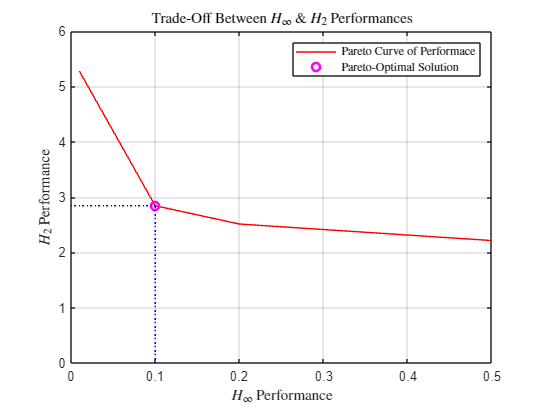

figure()
plot(g1opt, g2opt, 'r-')
hold on
plot(g1opt(2), g2opt(2), 'mo', LineWidth=2)
plot([0, g1opt(2)], [g2opt(2), g2opt(2)], 'b:');
plot([g1opt(2), g1opt(2)], [0, g2opt(2)], 'b:');
xlabel('$H_{\infty}$ Performance', 'Interpreter','latex')
ylabel('$H_2$ Performance', 'Interpreter','latex')
legend('Pareto Curve of Performace', 'Pareto-Optimal Solution', 'Interpreter','latex')
hold off
title('Trade-Off Between $H_{\infty}$ \& $H_2$ Performances','Interpreter','latex');
grid on;

By inspection of the Pareto curve of system performance, the state-feedback gain K obtained for g = 0.1 yields the best compromise between the H∞ and H2 objectives (i.e., is the Pareto-optimal solution).

[g1opt, g2opt, K, Pcl, X] = msfsyn(Pol, [1 1], [0.1 0 0 1], region) % For a prescribed H∞ performance g=0.1, compute the best H2 performance g2opt


 Optimization of   0.000 * G^2 +  1.000 * H^2 :
 ----------------------------------------------

 Solver for linear objective minimization under LMI constraints 

 Iterations   :    Best objective value so far 
 
     1
     2
     3
     4
     5
     6
     7
     8
     9
    10
    11
    12
    13
    14
    15
    16
    17
    18
    19
    20
    21
    22
    23
    24
    25
    26
    27
    28
    29
    30
    31                  11.070992
    32                  10.221470
    33                  10.221470
    34                   9.701670
    35                   9.701670
***                 new lower bound:    -2.292699
    36                   9.265248
***                 new lower bound:     0.859553
    37                   9.076602
***                 new lower bound:     2.121199
    38                   8.925003
***                 new lower bound:     3.664817
    39                   8.885049
***                 new lower bound:     4.647604
    40              

g1opt = 0.1000

g2opt = 2.8422

K =   -34.1783   -0.9348  -10.1852 -152.0596


Pcl =       -Inf         0         0         0    1.0000         0         0    4.0000         0         0         0    1.0000         0         0    4.0000         0         0         0    1.0000         0         0    4.0000         0         0         0    1.0000         0         0    4.0000
    1.0000         0         0         0         0    1.0000         0         0         0         0         0         0    1.0000         0         0         0         0         0         0    1.0000         0         0         0         0         0         0    1.0000         0         0
    4.0000         0  -34.2683   -0.8448  -10.1890 -152.0558    1.0000         0         0  -34.5783   -0.5348  -10.1890 -152.0558    1.0000         0         0  -34.2683   -0.8448  -10.2252 -152.0196    1.0000         0         0  -34.5783   -0.5348  -10.2252 -152.0196    1.0000         0
    4.0000         0    0.0900   -0.0900    0.0038   -0.0038         0         0         0    0.4000   -0.4000    0.0038 

X =     0.0078    0.0009   -0.0122   -0.0007
    0.0009    0.0013    0.0009   -0.0002
   -0.0122    0.0009    0.1136   -0.0005
   -0.0007   -0.0002   -0.0005    0.0002


psinfo(Pcl) % Print closed-loop system information

Polytopic model with 4 vertex systems 
    Each system has 4 state(s), 1 input(s), and 4 output(s)



Test robust stability of closed-loop system via parametric Lyapunov functions

[tmin, Q0, Q1, Q2, Q3] = pdlstab(Pcl, [0 0])


 Solver for LMI feasibility problems L(x) < R(x)
    This solver minimizes  t  subject to  L(x) < R(x) + t*I
    The best value of t should be negative for feasibility

 Iteration   :    Best value of t so far 
 
     1                        0.278648
     2                        0.085843
     3                        0.023653
     4                    4.194562e-04
     5                       -0.029220

 Result:  best value of t:    -0.029220
          f-radius saturation:  0.001% of R =  1.00e+07
 
 This system is stable in the specified parameter range


tmin = -0.0292

Q0 =    23.5169   10.3466   -3.3129   -4.6721
   10.3466   14.7447    4.8746   -2.7580
   -3.3129    4.8746   75.1022   -4.2893
   -4.6721   -2.7580   -4.2893    1.3600


Q1 =    23.5169   10.3466   -3.3129   -4.6721
   10.3466   14.7447    4.8746   -2.7580
   -3.3129    4.8746   75.1022   -4.2893
   -4.6721   -2.7580   -4.2893    1.3600


Q2 =    23.5169   10.3466   -3.3129   -4.6721
   10.3466   14.7447    4.8746   -2.7580
   -3.3129    4.8746   75.1022   -4.2893
   -4.6721   -2.7580   -4.2893    1.3600


Q3 =    23.5169   10.3466   -3.3129   -4.6721
   10.3466   14.7447    4.8746   -2.7580
   -3.3129    4.8746   75.1022   -4.2893
   -4.6721   -2.7580   -4.2893    1.3600


Analyse closed-loop system eigenvalues and impulse response

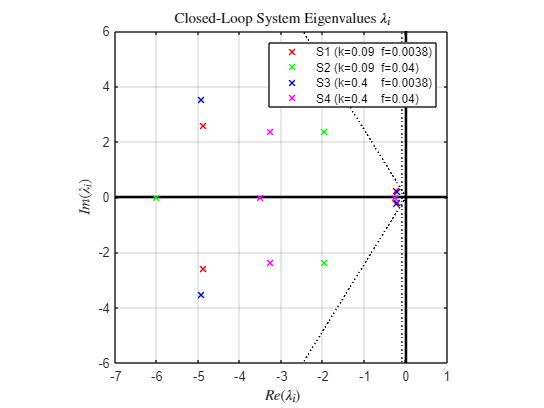

Pcl_kmin_fmin = psinfo(Pcl, 'sys', 1); % k=0.09 f=0.0038
Pcl_kmin_fmax = psinfo(Pcl, 'sys', 2); % k=0.09 f=0.04
Pcl_kmax_fmin = psinfo(Pcl, 'sys', 3); % k=0.4  f=0.0038
Pcl_kmax_fmax = psinfo(Pcl, 'sys', 4); % k=0.4  f=0.04

[A_kmin_fmin, B_kmin_fmin, C_kmin_fmin, D_kmin_fmin] = ltiss(Pcl_kmin_fmin);
[A_kmin_fmax, B_kmin_fmax, C_kmin_fmax, D_kmin_fmax] = ltiss(Pcl_kmin_fmax);
[A_kmax_fmin, B_kmax_fmin, C_kmax_fmin, D_kmax_fmin] = ltiss(Pcl_kmax_fmin);
[A_kmax_fmax, B_kmax_fmax, C_kmax_fmax, D_kmax_fmax] = ltiss(Pcl_kmax_fmax);

Pcl_kmin_fmin_ss = ss(A_kmin_fmin, B_kmin_fmin, C_kmin_fmin, D_kmin_fmin);
Pcl_kmin_fmax_ss = ss(A_kmin_fmax, B_kmin_fmax, C_kmin_fmax, D_kmin_fmax);
Pcl_kmax_fmin_ss = ss(A_kmax_fmin, B_kmax_fmin, C_kmax_fmin, D_kmax_fmin);
Pcl_kmax_fmax_ss = ss(A_kmax_fmax, B_kmax_fmax, C_kmax_fmax, D_kmax_fmax);

t = 0:0.01:20;

y_kmin_fmin = impulse(Pcl_kmin_fmin_ss, t);
y_kmin_fmax = impulse(Pcl_kmin_fmax_ss, t);
y_kmax_fmin = impulse(Pcl_kmax_fmin_ss, t);
y_kmax_fmax = impulse(Pcl_kmax_fmax_ss, t);

figure()
% Plot horizontal line passing through 0
plot([-10, 10], [0, 0], 'k-', 'LineWidth', 2);
hold on;
% Plot vertical line passing through 0
plot([0, 0], [-10, 10], 'k-', 'LineWidth', 2);
% Plot vertical line passing through -0.1
plot([-0.1, -0.1], [-10, 10], 'k:', 'LineWidth', 1);
% Plot two lines intersecting at 0 and manking an angle of (3*pi)/4 radians
angle = pi/2 + (pi - (3*pi)/4)/2; length = 10; x0 = 0; y0 = 0;
plot([x0, x0 + length * cos(angle)], [y0, y0 + length * sin(angle)], 'k:', 'LineWidth', 1);
plot([x0, x0 + length * cos(-angle)], [y0, y0 + length * sin(-angle)], 'k:', 'LineWidth', 1);
% Plot system eigenvalues
plot(real(eig(A_kmin_fmin)), imag(eig(A_kmin_fmin)), 'rx', LineWidth=1), grid
plot(real(eig(A_kmin_fmax)), imag(eig(A_kmin_fmax)), 'gx', LineWidth=1), grid
plot(real(eig(A_kmax_fmin)), imag(eig(A_kmax_fmin)), 'bx', LineWidth=1), grid
plot(real(eig(A_kmax_fmax)), imag(eig(A_kmax_fmax)), 'mx', LineWidth=1), grid
xlabel('$Re(\lambda_i)$','Interpreter','latex')
ylabel('$Im(\lambda_i)$','Interpreter','latex')
xlim([-7, 1])
ylim([-6, 6])
pbaspect([1 1 1])
grid('on')
title('Closed-Loop System Eigenvalues $\lambda_i$','Interpreter','latex')
legend('', '', '', '', '', 'S1 (k=0.09  f=0.0038)', 'S2 (k=0.09  f=0.04)', 'S3 (k=0.4    f=0.0038)', 'S4 (k=0.4    f=0.04)')

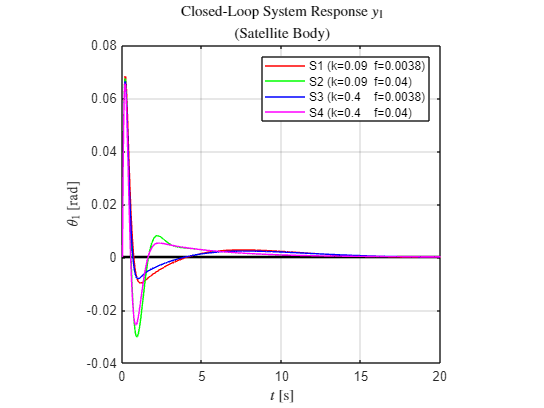


figure()
% Plot horizontal line passing through 0
plot([0, 20], [0, 0], 'k-', 'LineWidth', 2);
hold on;
% Plot system response
plot(t, y_kmin_fmin(:, 2), 'r-'), grid
plot(t, y_kmin_fmax(:, 2), 'g-'), grid
plot(t, y_kmax_fmin(:, 2), 'b-'), grid
plot(t, y_kmax_fmax(:, 2), 'm-'), grid
xlabel('$t$ [s]','Interpreter','latex')
ylabel('$\theta_1$ [rad]','Interpreter','latex')
xlim([0, 20])
ylim([-0.04, 0.08])
pbaspect([1 1 1])
grid('on')
title('Closed-Loop System Response $y_1$', '(Satellite Body)','Interpreter','latex')
legend('', 'S1 (k=0.09  f=0.0038)', 'S2 (k=0.09  f=0.04)', 'S3 (k=0.4    f=0.0038)', 'S4 (k=0.4    f=0.04)')

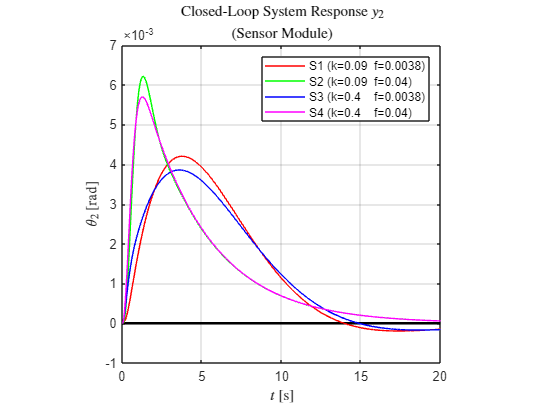


figure()
% Plot horizontal line passing through 0
plot([0, 20], [0, 0], 'k-', 'LineWidth', 2);
hold on;
% Plot system response
plot(t, y_kmin_fmin(:, 3), 'r-'), grid
plot(t, y_kmin_fmax(:, 3), 'g-'), grid
plot(t, y_kmax_fmin(:, 3), 'b-'), grid
plot(t, y_kmax_fmax(:, 3), 'm-'), grid
xlabel('$t$ [s]','Interpreter','latex')
ylabel('$\theta_2$ [rad]','Interpreter','latex')
xlim([0, 20])
ylim([-1e-3, 7e-3])
pbaspect([1 1 1])
grid('on')
title('Closed-Loop System Response $y_2$', '(Sensor Module)','Interpreter','latex')
legend('', 'S1 (k=0.09  f=0.0038)', 'S2 (k=0.09  f=0.04)', 'S3 (k=0.4    f=0.0038)', 'S4 (k=0.4    f=0.04)')